clear all
close all
sigmax=spinOp(5/2,'x');
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');

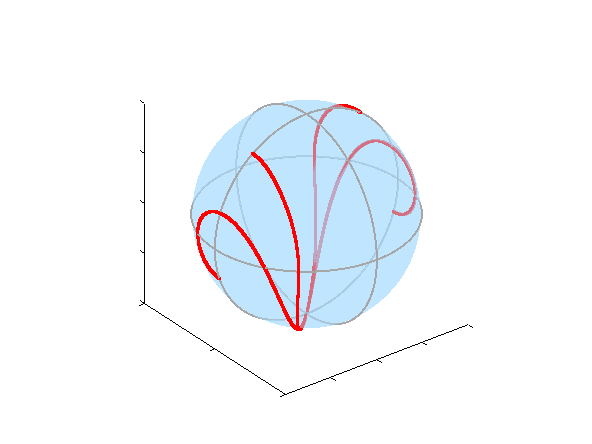

time_duration=(0:0.0001:0.5).*pi;
theta=[];phi=[];
for i=1:length(time_duration)
    time=time_duration(i);
    [theta0,phi0]=oneframe(time);
    theta=[theta;theta0];
    phi=[phi;phi0];
end
[x,y,z]=sph2cart(phi,pi/2-theta,1);
scatter3(x,y,z,'.','MarkerEdgeColor',[1 0 0],...
    'LineWidth',0.5);
daspect([1,1,1]);
hold on;

[theta2,phi2]=meshgrid([0:0.02:2*pi],[-pi/2:0.01:pi/2]);

[x0,y0,z0]=sph2cart(phi2,theta2,0.99);
mesh(x0,y0,z0,'FaceLighting','none',...
    'EdgeLighting','flat',...
    'FaceAlpha',0.5,...
    'FaceColor',[0.670588235294118 0.866666666666667 1],...
    'EdgeColor','none');



% 添加纬线
hold on
for theta = [0:pi/2:pi]
    phi=(0:0.01:2*pi);
    x = cos(phi) .* sin(theta);
    y = sin(phi) .* sin(theta);
    z=cos(theta).*ones(length(phi),1);
    l=plot3(x(:), y(:), z(:), 'r');
    l.LineWidth=1;
    l.Color=[0.65 0.65 0.65];
end

% 添加经线
hold on
for phi = [0:pi/2:2*pi]
    theta=(0:0.01:2*pi);
    x = cos(phi) .* sin(theta);
    y = sin(phi) .* sin(theta);
    z=cos(theta).*ones(length(phi),1);
    l=plot3(x(:), y(:), z(:), 'r');
    l.LineWidth=1;
    l.Color=[0.65 0.65 0.65];
    
end
grid off
axis vis3d
set(gca,'XColor','none','YColor','none',...
    'ZColor','none');

savefig('Majorana/trace.fig');

function [theta,phi]=oneframe(t)
    state1=[1 0 0 0 0 0]';
    sigmax=spinOp(5/2,'x');
    state_final=ham_evolve(sigmax^2,state1,t);
    [theta,phi]=findMS(state_final);

end
function [theta,phi]=findMS(state) % find majorana stars for the state
    poly_coeff=zeros(6,1);
    for i=1:6
        m=7/2-i;
        poly_coeff(i)=(-1)^(5/2+m)*sqrt(nchoosek(5,5/2+m))*state(i);
    end
    root=roots(poly_coeff);
    theta=acot(abs(root))*2; % 0 to pi 
    phi=angle(root); % -pi to pi

end
function f1=Qfunction(state)
    f1=figure;
    m=100;n=100;
    theta_list=[0:pi/(m-1):pi];
    phi_list=[0:2*pi/(n-1):2*pi];
    for i=1:length(theta_list)
        theta=theta_list(i);
        for j=1:length(phi_list)
            phi=phi_list(j);
            Qfunction_result(i,j)=scalar_product(state,spin_coherent(theta,phi));
        end
    end
    theta_list=pi/2-theta_list;
    [theta2,phi2]=meshgrid(theta_list,phi_list);
    [x,y,z]=sph2cart(phi2,theta2,1);
    surf=mesh(x,y,z,Qfunction_result');
    set(surf,'FaceLighting','none',...
    'EdgeLighting','flat',...
    'FaceColor','interp',...
    'EdgeColor','interp');
    xlim([-1 1]);
    zlim([-1 1]);
    ylim([-1 1]);
    daspect([1 1 1]);
    colormap jet
end
function state=spin_coherent(theta,phi)
sigmay=spinOp(5/2,'y');
sigmaz=spinOp(5/2,'z');
polar=[1 0 0 0 0 0]';
state1=ham_evolve(sigmay,polar,theta);
state=ham_evolve(sigmaz,state1,phi);
end
function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
function result=scalar_product(state1,state2)
    result=abs(ctranspose(state1)*state2).^2;
end
